# Gain Control and Building a Simple AGC Loop

Gain control is a fundamental operation in a receiver to adjust signal levels to a correct value.   In this lab, you will learn to:

- Mathematically model a receiver with variable gain and saturation

- Simulate the effect of gain and nonlinearities on the output SNR

- Manually control the gain on the SDR

- Measure the RX backoff of a received signal

- Build a simple AGC to maintain a target RX backoff

- Measure the RX power with gain

Files:  To run this lab, you will need to copy the completed `estChanResp.m` file from the [previous lab](matlab:open('../lab04_chansounder/estChanResp.m')) to the current directory.  

**Submissions**:  Run the lab with Pluto devices with either one or two hosts.   Fill in all sections labeled `TODO` .  Print and submit the PDF.  Do not submit the source code.

## Gain Control Theory

We can understand the role of gain control with the following simple model for a receiver.

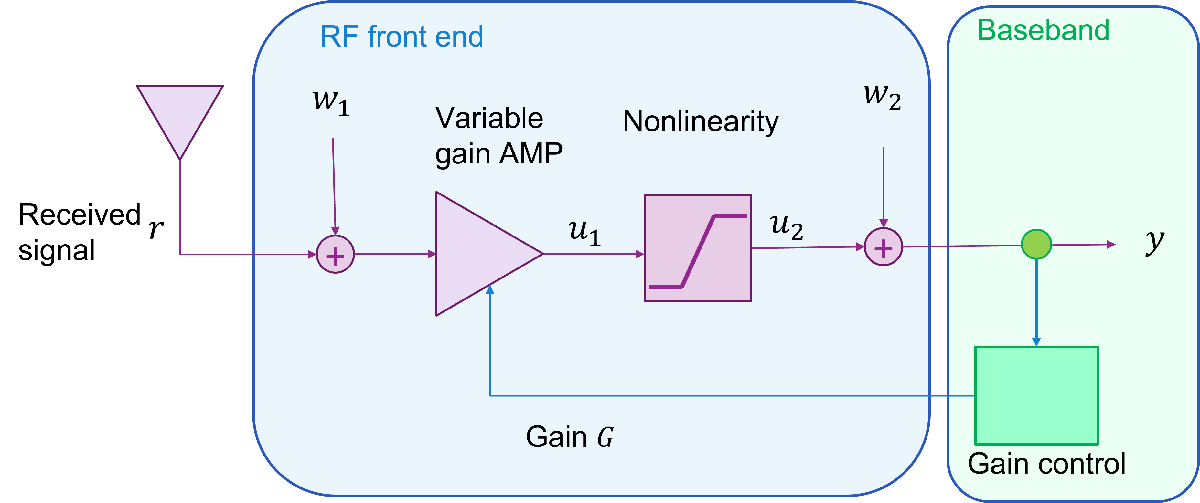

The receiver receives an RF signal (say from an antenna) that we denote `r`.  The signal is passed through an RF analog front-end to produce a signal `y` that is processed by the baseband.  The RF front-end itself has two stages.   For example, the first stage could be a low noise amplifier (LNA) and the second stage could be a mixer.  To make the analysis simple, let's consider very simple models for both stages.  We assume the first stage is a linear gain and thermal noise:

`    u1 = sqrt(gainRx)*(r+w1)     Erx = E|r|^2,  w1 ~ CN(0, wvar1)`

where `Erx `is the RX signal energy per sample, `wvar1` is the noise energy per sample, and gainRx is controllable gain.  The second stage has some nonlinearity:

`    y = u2 + w2 = nonlin(u1) + w2,  w2 ~ CN(0, wvar2).`

To analyze this receiver, first suppose there is no nononlinearity so that` u2 = u1.`  Then,  the RX resulting signal is:

`    y = sqrt(gainRx)*(r+w1) + w2 = sqrt(gainRx)*x + v,   v = sqrt(gainRx)*w1 + w2`

We can see that:

- The signal component in y has average energy: `Esig = gainRx*E|r|^2 = gainRx*Erx`

- The noise component in y has average energy: `Ev = E|v|^2 = gainRx*wvar1 + wvar2`

- The resulting output SNR is:  `snr = Esig/Ev = gainRx/(gainRx/snr1 + 1/snr2)`

where snr1 = Ex/wvar1 and `snr2=Ex/snr2`.  All values are in linear scale.  We call `snr` the output SNR since it is the SNR at the output of the RF front-end.  To get an idea of what this relation looks like, plot `snr` vs. `rxGain` using the values of `rxGain` in `rxGainTest`.  Note all values are in dB, so you will have to rewrite the above the formula above.  You should see that the SNR increases with the gain.  As the gain becomes very high, the SNR is limited to:

`     snr -> snr1   as gainRx -> infty`

snr1 = 30;  % Ex/wvar1 in first stage  in dB
snr2 = 10;  % Ex/wvar2 in second stage in dB
rxGainTest = linspace(0,40,100)';  % gain in dB

% TODO: 
%   snr = ...
%   plot(...);


The above plot suggests that we should make the gain as large as possible since the otuput SNR increases with the gain.  However, this analysis was valid only when there is no nonlinearity.  Most receiver components have a practical maximum input level. If the input signal goes beyond this level, the components start to operate nonlinearily and can distort the signal.  As a simple example in this lab, we will consider a saturation nonlinearity:

sat = @(x,a)  max(-a,min(a,real(x))) + 1i*max(-a,min(a,imag(x)));

The saturation clips the real and imaginary components of `x` to the range `[-a,a]`,  Hence if the input is small, the saturation does not distort the signal.  Specifically, if `u2=sat(u1,a)` then:

`   |real(u1)|,  |imag(u1)|<a  =>  u2=u1`

But, the input power of `u1` in the above figure is:

`    E|u1|^2 = gainRx*E|x + w|^2 = gainRx*(Ex + wvar1)`

So, increasing `gainRx` increases the input value and can eventually saturate the input.  

The goal of gain control is to select the gain, `gainRx, `to try to increase the signal level to overcome the noise but not push the signal into a nonlinear region.  We will see how to do this in both simulation and on the SNR.

## Creating the TX Waveform

We use the following parameters:

- `saveData`:  Indicates if the data is to be saved

- `usePreRecorded`:  Indicates if the data is to use the pre-save data.  This way, you will not need to run the device

% Parameters
saveData = true;
usePreRecorded = false;

We will use the same waveform that we used for channel sounding lab.  Complete the code below to create the signal.  Label the final signal as `x`.  

% Signal parameters
nfft = 1024;   % signal length
backoff = 9;   % backoff in dB
fsamp = 30.72e6*2;  % Sample rate in Hz
nsampsFrame = nfft; % Signal length


% Set the random generator to ensure that the TX and RX use the same data
rng(0,'twister');

if usePreRecorded
    load txData;
else
    % TODO:  Create a vector, xfd, of nfft random QPSK symbols.
    %   xfd = ...

    % Save frequency-domain TX data
    if saveData
        save txData xfd;
    end
end

% TODO: Take IFFT
%   x = ifft(...);

% TODO:  Rescale and clip values for the backoff.  You can use the
% saturation function sat above
%   x = sat(x,1);

## Simulating the Gain Control 

We will now simulate the above system with the following parameters.

wvar1 = 1;   % E|w1|^2 in linear scale
snr1 = 30;   % Erx / E|w1|^2 in dB
snr2 = 10;   % Erx / E|w2|^2 in dB
gainRx = 10; % RX gain in dB

First, using the above parameters, compute `wvar2` and the RX signal energy

% TODO:  
%   Erx = ...
%   wvar2 = ...


Next, as a simple model for the channel assume `r = chanGain*x`  where `chanGain` is set so that `Erx = ||r||^2`

% TODO:  
%   chanGain = ...
%   r = chanGain * x;  


Simulate the system:

% TODO:
%    w1 = ... 
%    w2 = ...
%    y = db2mag(gainRx)*(r + w1) + w2; 


To estimate the SNR, we will use [`estChanResp`](matlab:open('../lab04_chansounder/estChanResp.m')) function from the [previous lab](matlab:open('../lab04_chansounder/chanSounder.mlx')).  If you have completed this function, you can directly copy it to this directory.  Run this command to estimate the SNR and compare it to the theoretical value.  They should be close.

% TODO:
%   [~,~,snr] =  estChanResp(y,xfd,'normToNoise',true);
%   snrTheory = ...
%   fprintf(...);  % Print snr and snrTheory


% TODO:  Plot the estimated channel response in dB scale
%   t = ...;  % time in micro-seconds
%   stem(t, h,...);


% TODO:  Print snr and snrTheory
%  fprintf(1, ...);



Now, let's run the same code, this time varying the gain.  You should see that the theoretical SNR matches the measured value except at very low signal levels.  In this case, the `estChanResp` misdetects peaks and thinks there is a signal when there is not.  Hence, it over-estimates the SNR.  We will show in the next lab how to avoid this problem by simply ignoring snr levels below a certain threshold.  But, for now we will focus on the high SNR range where this problem does not occur.  

% Range of gain values to test
gainRxTest = linspace(-10,40,25)';
ngain = length(gainRxTest);
ntrials = 100;      % number of trials at each gain level

% Initialize vectors
snr = zeros(ngain,1);        % Median SNR measured at each gain level
snrTheory = zeros(ngain,1);  % Theoretical SNR with no non-linearity

% Loop over gain levels
for i = 1:ngain

    % Get gain to test
    gainRx = gainRxTest(i);
    snrIt = zeros(ntrials,1);

    for it = 1:ntrials
        
        % TODO:  Generate random noises and output y
        %    w1 = ...
        %    w2 = ...
        %    y = ...
     

        % TODO:  Estimate snr and store it in snrIt
        %   [~,~,snrIt(it)] =  estChanResp(...);
    end

    % Save the median SNR over the trials
    %    snr(i) = ...   
    
    % TODO:  Measure the theoretical SNR
    %    snrTheory(i) = ...
end

% TODO:  Plot the measured and theoretical SNR


Now, re-run the above code with a non-linearity.   When `abs(u1) << satLevLin, `the system is linear since `u2 ~= u`1.  But, once `u1` gets large the function begins to saturate, and there is a distortion.  At this point, the SNR stops increasing and, in fact, goes down slightly.  In this case, we are still getting a good SNR since there is a lot of averaging over many samples of the distortion.  But, at lower values of NFFT, the distortion would have more impact.

% Range of gain values to test
gainRxTest = linspace(-10,40,25)';
ngain = length(gainRxTest);
ntrials = 100;      % number of trials at each gain level

% Nonlinear parameters
satLev = 15;  %  Saturation level in dB above noise
satLevLin = sqrt( db2pow(satLev)*wvar1 );

% Initialize vectors
snrNL = zeros(ngain,1);      % Median SNR with non-linearity

% Loop over gain levels
for i = 1:ngain

    % Get gain to test
    gainRx = gainRxTest(i);
    snrIt = zeros(ntrials,1);

    for it = 1:ntrials
        
        % TODO:  Generate random noises and output with the non-linearity
        %    w1 = ...
        %    w2 = ...
        %    u1 = ...
        %    u2 = sat(u1,satLevLin);     
        %    y = ...

        % TODO:  Estimate snr and store it in snrIt
        %   [~,~,snrIt(it)] =  estChanResp(...);
 
    end

    % Save the median SNR over the trials
    %    snrNL(i) = ...

end


% TODO:  Plot the measured SNR with and without the non-linearity and
% theoretical SNR.  Add a legend to your plot so that you can see the
% different curves



## Measure the SNR on the SDR with a Fixed Gain

We will now run the above experiment using the SDR.  Following the [initial lab](http://../lab01_intro/samples.mlx),  set the mode to the desired configuration (loopback, two hosts with single host, or two hosts with two hosts).   

% TODO:  Set parameters
% Set to true for loopback, else set to false
loopback = false;  

% Select to run TX and RX
runTx = true;
runRx = true;

Plug one or two Plutos into the USB ports of your computer.  If it is correctly working, in each device the Ready light should be solid on and the LED1 light should be blinking.   Next, run the following command that will detect the devices and create the TX and RX ob

% clear previous instances
clear tx rx

% add path to the common directory where the function is found
addpath('..\common');


% Run the creation function.  Skip this if we are using pre-recorded
% samples
if ~usePreRecorded
    [tx, rx] = plutoCreateTxRx(createTx = runTx, createRx = runRx, loopback = loopback, ...
        nsampsFrame = nsampsFrame, sampleRate = fsamp);
end

Now TX the clipped data `x` repreatedly through the Pluto device.  

if runTx && ~usePreRecorded
    % TODO:  Use the tx.release() and tx.transmitRepeat() commands to
    % continuously send x
    
end
% If not running the RX, stop the live script now
if ~runRx
    return;
end

A very nice feature of the Pluto devices is that they have an automatic gain control (AGC) that brings the signal correctly to the right level.  In this lab, we will disable this feature to manually control the gain.  We can set the gain manually as follows: The gain range is shown in [comm.SDRRxPluto webpage ](https://www.mathworks.com/help/supportpkg/plutoradio/ref/comm.sdrrxpluto-system-object.html)of Mathworks with the minimum and maximum Rx gain below.  

% Gain range in dB
gainRxMin = -3;
gainRxMax = 71;

% Place the Pluto in manual gain mode.  When you do this the first time,
% you will need to release it
if ~usePreRecorded
    rx.release();
    rx.set('GainSource', 'Manual');
end

% Manual gain setting.  You may need to change this value to get a good response in the next step
if loopback
    gainRx = 20;      
else
    gainRx = 50;
end
if ~usePreRecorded
    rx.set('Gain', gainRx);
end


On the RX Pluto device, receive the data

nbits = 12;               % number of ADC bits
fullScale = 2^(nbits-1);  % full scale

if ~usePreRecorded

    % TODO:  Capture data
    %   y = rx.capture(...)
    
    % TODO:  Scale to floating point
    %   y = ...

    % Save the data
    if saveData
        save rxDataSing y;
    end
  
else 
    % Load pre-recorded data
    load rxDataSing;

end

% TODO:  Measure the channel response and SNR with the estChanResp function

% TODO:  Plot the channel response



We will now run the test over multiple gains.  Unforunately, in the MATLAB interface, manually changing the gain is slow, so the sweep takes considerable time.

% Rx gain levels to test
gainRxTest = linspace(0,60,7)';
ngain = length(gainRxTest);

% Number of trials per gain step
ntrials = 10;

% SNR and RX signal energy per sample in trial and gain
snr = zeros(ngain,ntrials);
ypow = zeros(ngain,ntrials);

% Get pre-recorded data if requested
if usePreRecorded
    load rxDatGain;
else
    ydat = zeros(nsampsFrame,ngain,ntrials);
end


% Loop over gain levels
for i = 1:ngain

    % Get gain to test
    gainRx = gainRxTest(i);

    % Set the gain
    if ~usePreRecorded        
        rx.set('Gain', gainRx);
    end
    

    % Loop over trials
    snrIt = zeros(ntrials,1);   
    for it = 1:ntrials
                       
        if usePreRecorded
            y = ydat(:,i,it);
        else
            % TODO:  Get the data and convert to floating point
            %    y = rx.capture(...)
        end

        % Save the data
        ydat(:,i,it) = y;

        % TODO:  Estimate snr and store it snr(i,it)
        %   [~,~,snr(igain,it)] =  estChanResp(...);

        % TODO: Measure the energy per sample in y and store it in ypow
        %   ypow(i,it) = ...
    end

    % Print the gain and median SNR
    fprintf(1,'gainRx = %.2f snr=%.2f\n', gainRx, median(snr(i,:)));
  
end

% Save the data
if saveData
    save rxDatGain ydat;
end

To analyze these results compute two quanties.  First, we compute the median SNR for each gain level `i`:

`  snrMed(i) = median(snr(i,:));`

Next, we compute the rx backoff

`  rxBackoff(i) = -pow2db(median(ypow(i,:))/2);      `

Recall that the input is full scale when `|real(y)|=|imag(y)|=1`.  So, at the maximum input level, we have `|y|^2=2`.  Hence the RX backoff represents how far below the actual signal is relative to the full scale.

Compute and plot `snrMed` and `rxBackoffMed` for the data you have collected.  You should see that the as the RX gain increases, the median SNR initially increases.  If you are in loopback mode, you will see that the SNR starts to eventually decreases.  The decrease is due to the fact that we are saturating the receiver.  With two devices at a reasonable disance, the RX may never saturate depending on the TX power setting.

For both cases, you should see that the rxBackoff decreases.

% TODO:  Compute median SNR
%    snrMed = median(...);

% TODO:  Compute median backoff
%    ypowMed = median(...);


subplot(1,2,1);
% TODO:  Plot snrMed vs. gainRxTest.  Label your axes


subplot(1,2,2);
% TODO:  Plot rxBackoffMed vs. gainRxTest.  Label your axes



## Building a Simple AGC Loop

In this final part of the lab, we will build a very simple AGC loop.  The key idea is that we know the signal is in a good range when `rxBackoff` is some reasonable value like 12 dB.  A common technique in an AGC loop is to try to adjust the gain to maintain some target backoff.  In this case, we will take a target `rxBackoffTgt = 12` dB.  You can implement this loop by completing the code.   In each iteration `it` of the loop, we:

- Set the gain with a value `gainRx(it)`

- Measure the energy per sample ypow`(it)`

- Measure the RX backoff from `rxBackoff(it)`

- Increase the gain if `rxBackoff(it) > rxBackoffTgt` and decrease it if `rxBackoff(it) < rxBackoffTgt.  `Set the new gain in `rxGain(it+1)`

For the update in the final step, I suggest an update of the form:

`     gainRx(it+1) = gainRx(it) + step`

I will let you try to figure out a good step increase.  To keep the loop stable, I limit the `step` to -`stepMax` to `stepMax`.  

We will also measure the received power.  When the RF front end is in the linear regime, we know that:

 `   E|y|^2 ~= c*rxGain*rxPow `

where rxPow is the power at the input to the RF front end and `c` is some proportionality constant.  Therefore, in dB, we can estimate the relative receive power:

       `rxPow(it) = db2pow(ypow) - gainRx(it);`

Note that this is only a relative power value.  For an absolute power value, we need to calibrate with a known input.

% Number of iterations
nit = 100;

% RX backoff target in dB
rxBackoffTgt = 12;

% Initialize arrays to store data
snr = zeros(nit,1);             
rxBackoff = zeros(nit,1);       
gainRx = zeros(nit,1);
rxTime = zeros(nit,1);
rxPow = zeros(nit,1);

% Get pre-recorded data, if requested
if usePreRecorded
    load rxDatContinuous;
else
    ydat = zeros(nsampsFrame,nit);

    rx.release();
    rx.set('GainSource', 'Manual');
end

% Initialize RX gain
gainInit = 0;
gainRx(it) = gainInit;

% Initialize plots
clf;
subplot(1,2,1);
snrToNow = [0,0];
timeToNow = [0,3];
psnr = plot(timeToNow,snrToNow, 'o-', 'LineWidth', 2);
ylim([0,60]);
xlabel('Time [sec]');
ylabel('SNR[dB]');
grid on;

subplot(1,2,2);
rxPowToNow = [-50,50];
ppow = plot(timeToNow,rxPowToNow, 'o-', 'LineWidth', 2);
%ylim([-80,0]);
xlabel('Time [sec]');
ylabel('RX power [dB]');
grid on;


% Set pointers to X and Y data for both plots
psnr.XDataSource = 'timeToNow';
psnr.YDataSource = 'snrToNow';
ppow.XDataSource = 'timeToNow';
ppow.YDataSource = 'rxPowToNow';

for it = 1:nit
    
    if usePreRecorded
        y = ydat(:,it);
    else
        % TODO:  Set the gain to gainRx(it)
        %   rx.set(...);

        % TODO:  Get the data and convert to floating point
        %   y = ...
    end    
    ydat(:,it) = y;

    % Get the time
    if (it==1)
        tic;
    end    
    rxTime(it) = toc();

    % TODO:  Estimate the snr 
    %   [~,~,snr(it)] =  estChanResp(...);

    % TODO:  Estimate the energy per sample, RX backoff and RX power
    %    ypow = ...
    %    rxBackoff(it) = ...
    %    rxPow(it) = ...
    
    if (it < nit-1)
    
        % TODO: Compute the gain step.  
        %   step = ...

        % Limit the step size
        stepMax = 10;
        step = max(min(stepMax, step), -stepMax);

        % TODO:  Update the gain for the next iteration
        %    gainRx(it+1) = ...
        gainRx(it+1) = gainRx(it) + step;
        
        % Limit the gain to the max and minimum values and ensure the value
        % an integer
        gainRx(it+1) = max(gainRxMin, gainRx(it+1));
        gainRx(it+1) = min(gainRxMax, gainRx(it+1));
        gainRx(it+1) = round(gainRx(it+1));
    end
     
    % Update the plots
    snrToNow = snr(1:it);
    timeToNow = rxTime(1:it);
    rxPowToNow = rxPow(1:it);
    refreshdata;
    drawnow;

end

if saveData
    save rxDatContinuous ydat;
end

## Further Enhancements

So far, we have built a very slow AGC.  In real systems, the AGC needs to converge within a few microseconds and is generally implemented with a dedicated hardware feedback loop.  This is the normal setting for the Pluto.  But, the above lab is useful to illustrate the key concepts.  If you want to do more:

- Improve the RX measurements with time averaging

- Measure the path loss in different distances to study propagation (we will cover this in the wireless class)

- Calibrate the system

- Add misdetection logic (we will do this in the next lab)